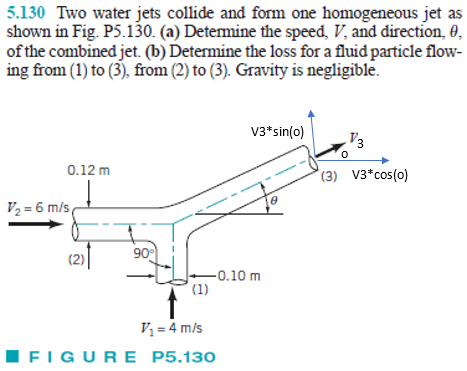

# given

u = symunit;
rho = 1000*u.kg/u.m^3;
g = 9.81*u.m/u.s^2;

# inflow properties

% ----------------
D1 = 0.10*u.m;
A1 = sympi*D1^2/4;
V1 = 4*u.m/u.s;
V1x = 0;
V1y = V1;
mdot1 = rho*A1*V1;
% ----------------
D2 = 0.12*u.m;
A2 = sympi*D2^2/4;
V2 = 6*u.m/u.s;
V2x = V2;
V2y = 0;
mdot2 = rho*A2*V2;
% ----------------

# outflow properties

syms A3 V3 theta positive;
V3x(V3, theta) = V3*cos(theta);
V3y(V3, theta) = V3*sin(theta);
mdot3(A3, V3) = rho*A3*V3;

# conservation of mass

eqn = sym.zeros(3,1);
eqn(1) = mdot1+mdot2 == mdot3;

# conservation of linear momentum (x-direction)

eqn(2) = 0 == -mdot1*(V1x)-mdot2*(V2x)+formula(mdot3)*formula(V3x);

# conservation of linear momentum (y-direction)

eqn(3) = 0 == -mdot1*(V1y)-mdot2*(V2y)+formula(mdot3)*formula(V3y);

# speed and direction and section 3

[A3 V3 theta] = solve(eqn, [A3 V3 theta]); %#ok
A3 = simplify(A3);
V3 = simplify(V3);
V3_vpa = vpa(V3, 3) %#ok

$$V3\_vpa = 4.29\,\frac{m}{s}$$

theta = rewrite(theta*u.rad, u.deg);
theta_vpa = vpa(theta, 4) %#ok

$$theta\_vpa = 17.15\,\deg$$

clear V3_vpa theta_vpa;
clearassum;

# head losses

syms loss_13 loss_23;
loss_13 = solve(mdot1*V3^2/2 == mdot1*V1^2/2-loss_13);
loss_13 = rewrite(loss_13, u.W);
loss_13_vpa = vpa(loss_13, 4) %#ok

$$loss\_13\_vpa = -38.06\,W$$

loss_23 = solve(mdot2*V3^2/2 == mdot2*V2^2/2-loss_23);
loss_23 = rewrite(loss_23, u.W);
loss_23_vpa = vpa(loss_23, 5) %#ok

$$loss\_23\_vpa = 596.38\,W$$

total_loss = loss_13+loss_23;
total_loss_vpa = vpa(total_loss, 5)

$$total\_loss\_vpa = 558.33\,W$$

clear loss_13_vpa loss_23_vpa total_loss;